clear all;
Eisen1_r2 = load('/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen1_r2.mat');
Eisen1_r3 = load('/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen1_r3.mat');
Eisen2_r2 = load('/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen2_r2.mat');
Eisen2_r3 = load('/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen2_r3.mat');

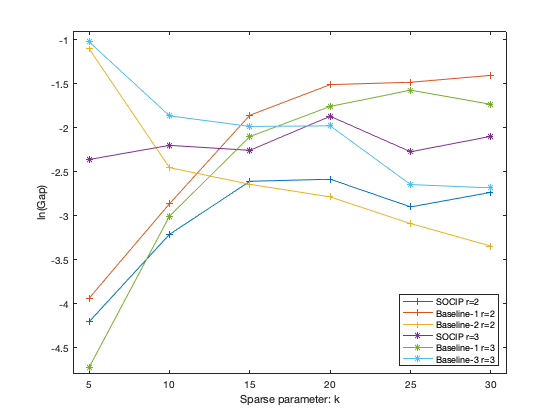

k = [5,10,15,20,25,30];
% Plot Eisen 1
plot(k, Eisen1_r2.data(:,1),'-+',k, Eisen1_r2.data(:,2),'-+', k, Eisen1_r2.data(:,3),'-+',...
    k, Eisen1_r3.data(:,1),'-*',k, Eisen1_r3.data(:,2),'-*',k, Eisen1_r3.data(:,3),'-*');
xlim([4,31]);ylim([-4.8,-0.9]);
xlabel('Sparse parameter: k');ylabel('ln(Gap)');
legend('SOCIP r=2',"Baseline-1 r=2", "Baseline-2 r=2",...
    "SOCIP r=3", "Baseline-1 r=3", "Baseline-2 r=3",'Location','southeast');
print(gcf,'-r300','-depsc','/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen1.eps');

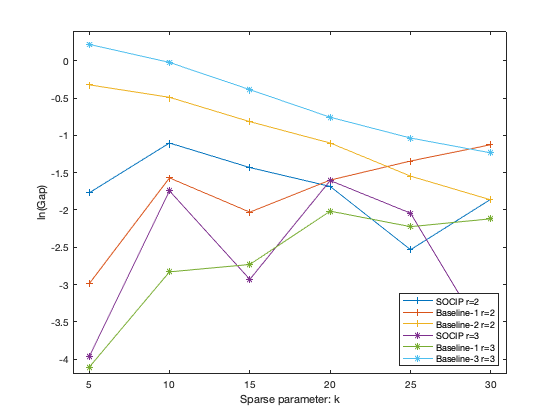


% Plot Eisen 2
plot(k, Eisen2_r2.data(:,1),'-+',k, Eisen2_r2.data(:,2),'-+', k, Eisen2_r2.data(:,3),'-+',...
    k, Eisen2_r3.data(:,1),'-*',k, Eisen2_r3.data(:,2),'-*',k, Eisen2_r3.data(:,3),'-*');
xlim([4,31]);ylim([-4.2,0.4]);
xlabel('Sparse parameter: k');ylabel('ln(Gap)');
legend('SOCIP r=2',"Baseline-1 r=2", "Baseline-2 r=2",...
    "SOCIP r=3", "Baseline-1 r=3", "Baseline-2 r=3",'Location','southeast');
print(gcf,'-r300','-depsc','/Users/taou/OneDrive - shanghaitech.edu.cn/Courses/CS240. Machine Learning/RowSPCA-CS282-Machine-Learning-Course-Project/result/Eisen2.eps');